# Rigid Transformations in 3D

Citation: [pctransform example](matlab: openExample('vision/Rotate3DPointCloudUsingRigidTransformationExample')) 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

To model 3D objects moving through space, we need to describe how rigid transformations occur mathematically. There are MATLAB® functions and Simulink® blocks that will compute these transformations, but to apply them properly, you need to have some idea of what information is needed and which default assumptions you may want to change. Before we move on to vehicles that are designed to fly, let's consider a teapot. 

 
ptCloud = pcread('teapot.ply');
figure
pcshow(ptCloud)
lim = 5;
DecoratePlot(lim)
function DecoratePlot(lim)
% Standardize the labels and limits of the output plot
xlabel("X")
xlim([-lim lim])
ylabel("Y")
ylim([-lim lim])
zlabel("Z")
zlim([-lim lim])
end

Create a transform object by 

- setting rotation values around the x, y, and z-axes. 

x_rot = 30; % degrees from -180 to 180
y_rot = 45; % degrees from -180 to 180
z_rot = 60; % degrees from -180 to 180
rot = rotationMatrix(x_rot,y_rot,z_rot);

         2. setting translation values along the x, y, and z-axes.

x = 2;
y = -3;
z = 4;
trans = [x, y, z];

Use the [`rigidtform3d`](https://www.mathworks.com/help/images/ref/rigidtform3d.html) to create a transform object with both the rotational and translational components.

tform = rigidtform3d(rot,trans)

tform1 = rigidtform3d(rotationMatrix(x_rot,0,0),[x y z]);
tform2 = rigidtform3d(rotationMatrix(0,y_rot,0),[0 0 0]);
tform3 = rigidtform3d(rotationMatrix(0,0,z_rot),[0 0 0]);
 

Transform the point cloud incrementally using first `tform1`, then rotating the result by applying `tform2`, and finally rotating using `tform3`.

 
ptCloudOut1 = pctransform(ptCloud,tform1);
pcshow(ptCloudOut1);
DecoratePlot(lim)
ptCloudOut2 = pctransform(ptCloudOut1,tform2);
pcshow(ptCloudOut2)
DecoratePlot(lim)
ptCloudOut3 = pcshow(pctransform(ptCloudOut2,tform3));
DecoratePlot(lim)

Transform the point cloud using the full transform.

 
ptCloudOut = pctransform(ptCloud,tform);

Plot the transformed point cloud.

figure
teapot = pcshow(ptCloudOut);
DecoratePlot(lim)

  **Try**. 

- Switch the variables defined as `tform1` and `tform3`. Does the result match the full transform version?

- Change the values of the sliders and predict where the teapot will end up. Can you make it flip upside down? Can you make it leave the frame?

As a product of matrices, these transforms are non-commutative. That is, the order in which they are performed matters. If we rotate first around the $z$-axis, then the $y$-axis, then the $x$-axis, we'll end up in a different orientation than if we rotate around the $x$-axis first, then the $y$-axis, then the $z$-axis. If you do not specify the entire rotation matrix yourself, you must understand the conventions used by the functions to create one. 

When specifying 3D rotations using Euler angles, it is important to distinguish between **extrinsic** and **intrinsic** rotation order. In extrinsic rotations, each rotation is applied about the *fixed, global axes* (e.g., rotate about global $x$, then global $y$, then global $z$). In intrinsic rotations, each rotation is applied about the *body-fixed axes*, meaning each subsequent rotation is about an axis that has already been rotated.

In `rigidtform3d`, Euler angles are interpreted as intrinsic rotations about the $x$, then the $y$, then the $z$ axes of the *rotating frame*. Internally, this results in a rotation matrix of the form

$R = R_z(\psi)\,R_y(\theta)\,R_x(\phi)$,

where the angles $[\phi,\theta,\psi]$ correspond to rotations about $x$, then $y'$, then $z''$. This is mathematically equivalent to an extrinsic $z$-$y$-$x$ rotation applied about fixed axes, but the interpretation matters when reasoning about physical motion and frame changes. Intrinsic computations make sense for navigation, as the object in motion most commonly measures its own location and orientation in space. This object-centered orientation makes it simpler to track "turn right" rather than determining which angle corresponds to the "turn right" action with respect to a fixed global coordinate system at each point along a trajectory. 

 **Exercise. **Use a `for` loop to create an animation that moves the teapot from the original position to the new position over a reasonable number of steps to appear smooth but not too slow. 

% Define the number of steps to use
iteration_number = 1;  % Change the value of 1 to the number of steps you want

% Define a path from the origin to your endpoint in each coordinate, 
%     such as by defining linearly spaced steps

% Rotation around x-axis

% Rotation around y-axis

% Rotation around z-axis

% Translation in the x direction

% Translation in the y direction

% Translation in the z direction


% Plot your original point cloud
tp = pcshow(ptCloud);  % Don't change this line


for idx = 1:iteration_number
    % Generate the rigid transform of your figure at idx steps into the
    % animation and generate a new point cloud called ptCloudOut to replace
    % the default value of ptCloud




    ptCloudOut = ptCloud;  % Change ptCloud to be the transformed point cloud

    % This code updates the points in the diagram
    tp.Children.XData = ptCloudOut.Location(:,1); % Do not change
    tp.Children.YData = ptCloudOut.Location(:,2); % Do not change
    tp.Children.ZData = ptCloudOut.Location(:,3); % Do not change
    pause(0.05); % Pause for a brief moment to visualize the rotation
end

  **Pro-tip**. Did you use `linspace` to define your steps?.

 **Reflect**.

- How would you combine [projectile motion](matlab:open('./ProjectileMotion.mlx')) with rotational motion?

Finally, we can model the same 6-degree-of-freedom mathematics conveniently in Simulink using the Aerospace Blockset. In this model, a rectangular plate is moved through space while rotating: [**Modeling a Six Degree of Freedom Motion Platform**](https://www.mathworks.com/help/aeroblks/six-degree-of-freedom-motion-platform.html)

**Note:** Examples are downloaded from the internet, which may be slow and may require additional toolboxes. This example uses the Aerospace Blockset.

openExample('aeroblks/ModelingASixDegreeOfFreedomMotionPlatformExample');
 

Without getting into the details of the model, the important block to note is the 6DOF block, which takes xyz forces and moments as inputs and models the motion of the body. When we provide force and moment input values (e.g., from the propellers of a quadcopter drone), we can use this block to calculate the object's motion over time. 

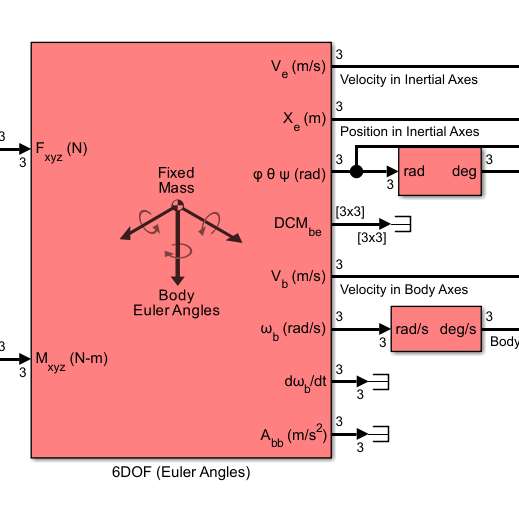

These types of ready-made blocks make coding simpler for a design engineer who does not need to worry too much about the computational mathematics, and can focus more on the design of the system. Note that this is just an example of how the 6DOF block works and is not intended to represent how a real drone moves - that will come later, along with a more detailed explanation of creating models in Simscape.

Each example will open in a new tab and switch to a new file location. When you are done exploring the example, close the files that were opened, return to this script, and click the "Return Here" button. This will reset your file location to the root folder for this content collection.

## Rotations, Orientation, and Quaternions

There are many ways to represent spatial rotations, including Euler angles, rotation matrices, and quaternions. To interface naturally with an animation block we'll use to visualize quadcopter flight, we will choose blocks that calculate with quaternions. Learn the basics of quaternion arithmetic in the following example.

openExample("shared_positioning/QuaternionExample");
 

## **Further Explorations**

If you like the teapot example, you might want to learn more about Simscape™ Multibody™ in the [Multibody Simulation Onramp](https://matlabacademy.mathworks.com/details/multibody-simulation-onramp/ormb) or go deeper into the mathematics in the [Robotic Manipulators](https://www.mathworks.com/matlabcentral/fileexchange/130124-robotic-manipulators) courseware.

Cleve Moler wrote an application called [`Grafix`](https://blogs.mathworks.com/cleve/files/Grafix_mzip-1.m) which allows you to [visualize both the position and orientation of an object](https://blogs.mathworks.com/cleve/2021/10/20/roll-yaw-pitch-taxi-and-more/) and the [transformation matrix](https://blogs.mathworks.com/cleve/2021/10/03/the-matrix-at-the-heart-of-computer-graphics/) that gets you there. Instructions for using this tool are in the [Grafix User's Guide](https://blogs.mathworks.com/cleve/2023/02/10/grafix-users-guide).

Applications of this include animations, such as this documentation example that overlays [simulated and actual flight data](https://www.mathworks.com/help/aerotbx/ug/overlaying-simulated-and-actual-flight-data.html).

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

Calculate a rotation matrix given rotations `x_rot`, `y_rot`, and `z_rot` in degrees. 

function rot = rotationMatrix(x_rot,y_rot,z_rot)

% for x-rotation
phi = deg2rad(x_rot);
Rx = [1 0         0       ; ...
      0 cos(phi) -sin(phi);...
      0 sin(phi)  cos(phi)];
  
% for y-rotation
theta = deg2rad(y_rot);  
Ry = [cos(theta) 0  sin(theta); ...
      0          1  0         ;...
     -sin(theta) 0  cos(theta)];

% for z-rotation
psi = deg2rad(z_rot);
Rz = [cos(psi) -sin(psi) 0;...
      sin(psi)  cos(psi) 0;...
      0         0        1];

% First rotate around the z-axis, then the y-axis, and finally the x-axis
rot = Rx*Ry*Rz;  

end

function ReturnHere() %#ok<DEFNU>
curloc = matlab.desktop.editor.getActiveFilename;
if contains(curloc,"Scripts")
    rootdir = extractBefore(curloc,filesep+"Scripts");
elseif contains(curloc,"InstructorResources")
    rootdir = extractBefore(curloc,filesep+"InstructorResources");
else
    error("Unexpected location: " + curloc)
end
cd(rootdir)
end

*© *Copyright 2026 The MathWorks, Inc